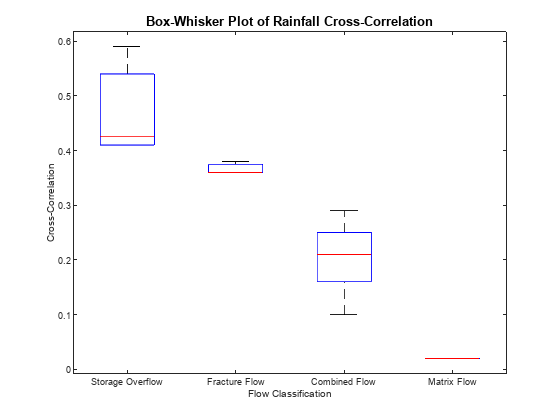

% Define the actual data for each group based on the given ranges
% Group 1 (0.41 to 0.59)
group1 = [0.53, 0.59, 0.55, 0.44, 0.41, 0.41, 0.41, 0.41];

% Group 2 (0.36 to 0.38)
group2 = [0.38, 0.36, 0.36];

% Group 3 (0.10 to 0.29)
group3 = [0.29, 0.21, 0.25, 0.25, 0.21, 0.10, 0.14, 0.18];

% Group 4 (0.02) - Make sure it's a column vector (even if it contains one value)
group4 = [0.02];  % This is now explicitly a column vector

% Find the maximum length of any group to determine how much padding we need
maxLength = max([length(group1), length(group2), length(group3), length(group4)]);

% Pad each group with NaN to ensure they have the same length
group1_padded = [group1(:); NaN(maxLength - length(group1), 1)];
group2_padded = [group2(:); NaN(maxLength - length(group2), 1)];
group3_padded = [group3(:); NaN(maxLength - length(group3), 1)];
group4_padded = [group4(:); NaN(maxLength - length(group4), 1)];

% Combine the padded groups into a matrix for boxplot
data = [group1_padded, group2_padded, group3_padded, group4_padded];

% Create a box-whisker plot
f = figure;
%boxplot(data, 'Labels', {'0.41-0.59', '0.36-0.38', '0.10-0.29', '0.02'});
boxplot(data, 'Labels', {'Storage Overflow', 'Fracture Flow', ...
    'Combined Flow', 'Matrix Flow'});

ax = gca; % Get current axes
ax.XTickLabelRotation = 0; % Set x-axis labels to 0 degrees
ax.FontSize = 7;                % Adjust font size of tick labels

% Add title and labels
title('Box-Whisker Plot of Rainfall Cross-Correlation','FontSize', 10 );
xlabel('Flow Classification', 'FontSize', 8);
ylabel('Cross-Correlation', 'FontSize', 8);

% Save the figure
%saveas(f, 'Box-Whisker Plot Rainfall.png');  % Saves the current figure
saveas(f, 'Box-Whisker Plot Rainfall labelZero8.png');  % Saves the current figure

%exportgraphics(f, 'Box-Whisker Plot Rainfall Res15.png', 'Resolution', 1500);  % Save with 1500 DPI resolution
